# Test/ Debugger: imgCropMULTI 

**Summary: **Works through step by step the preprocessing and cropping stages. Useful for code debugging and investigating preprocessing quality of a particular frame.

**User notes:**

1) Make sure videos and individual video frames that wished to be investigated are located in the same folder as this live script.

2) Ammend necessary inputs, particularly video/ image file name. Other hyperparameters can also be adjusted as see fit.

V1.1. SWC, 10 Feb 2021.

## 1) Load video

% vid_file_name = 'SO5_13umL-7Wat_umL-10kfps x4mag_sh50_C001H001S0026.avi'; %<-------- user-defined input!!
vid_file_name = '52%Gl_W_0.003_Ink_SO_SPAN80_0.003_2kfps_.avi';
vid = VideoReader(vid_file_name); %read video 
totframes = vid.NumFrames %check total num of frames in video

totframes = 5741

## 2a) Background generation - 'Basic'

Shows 3 methods: i) Mean, ii) Median and iii) Mode

n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
mean_pix = mean(frameMat,3,'native'); %compute mean of each pixel across all frames in matrix
toc

Elapsed time is 2.834664 seconds.



tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 0.323563 seconds.


tic
max_pix = mode(frameMat,3); %compute mode of each pixel across all frames in matrix
toc

Elapsed time is 1.198886 seconds.


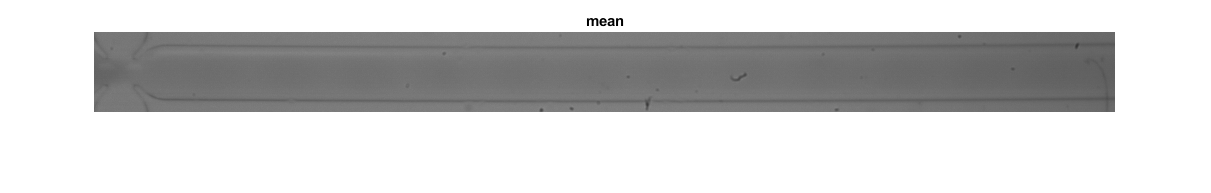

%show generated background 
figure; imshow(mean_pix); title('mean'); % to use imshow with 'double' class type, need to rescale to range [0 1]

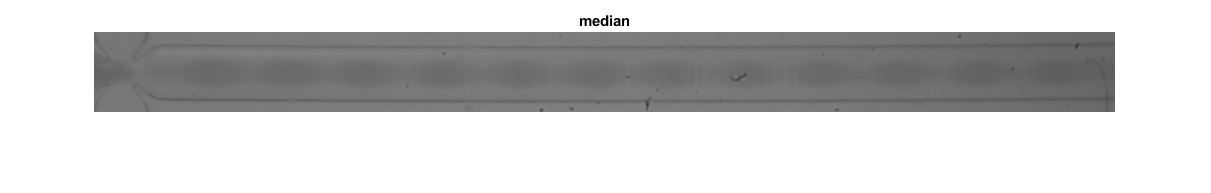

figure; imshow(med_pix); title('median')

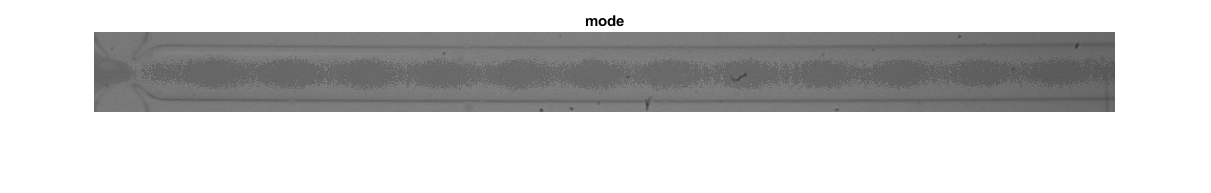


figure; imshow(max_pix); title('mode')

## 2b) Background generation - 'Complex' 

### (Adapted from ADM method: Chong et al., 2016)

n = 40;    % number of frames to use for background generation

idx = randperm(totframes,n); %vector of index of frame number to be extracted; randomly selected
frameMat = [];

% for loop to create matrix of frames - for generating background image
for j=1:numel(idx)
    frame = read(vid,idx(j));
    frameMat = cat(3,frameMat,frame);
end

bg = mean(frameMat,3,'native'); %compute mean value of each pixel across all frames in matrix

Imin = double(min(bg,[],'all'))

Imin = 53

Imax = double(max(bg,[],'all'))

Imax = 135

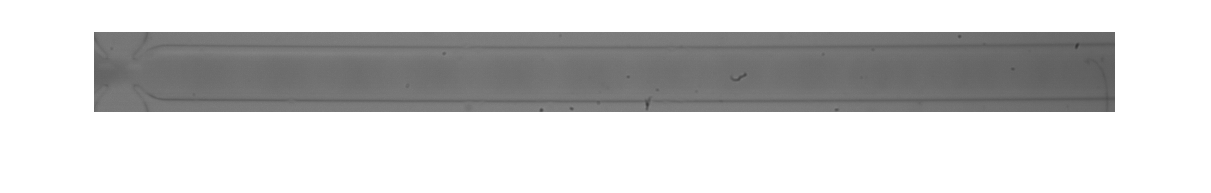


figure; imshow(bg)

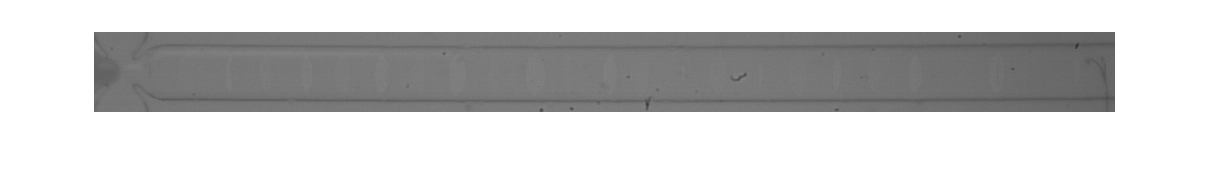

f = randperm(totframes,n);

Al2 = (245*(double(bg)-Imin))/(Imax-Imin) + 10;
R = bg;

for nf = 1:length(f)
    F = read(vid, f(nf));
    Fl2 = (245*(double(F)-Imin))/(Imax-Imin) + 10;
    
    D = 255.* Fl2 ./ Al2;
    D(Al2 <= 0 | Fl2 > Al2) = 255;
    D(Fl2 < 0) = 0;
%     D = mat2gray(D);
    D = rescale(D);
    
    B1 = imbinarize(D);
    B2 = imcomplement(B1);
    
    B2_fill = bwconvhull(B2,'object');
    B2_fill = bwareaopen(B2_fill,1000);
    A2 = regionprops('table',B2_fill,'BoundingBox');
    se = strel('disk', round(0.2*min(A2.BoundingBox(:,3))));
    B2_dilate = imdilate(B2_fill,se);
    M2 = uint8(double(R).*double(B2_dilate));
    
    B1_dilate = imcomplement(B2_dilate);
    M1 = uint8(double(B1_dilate).*double(F));
    
    R = M1+M2;
    
    %     figure; imshow(M1); figure; imshow(M2);
    %     figure; imshow(R);
    
end

figure; imshow(R)

## 3) Load image 

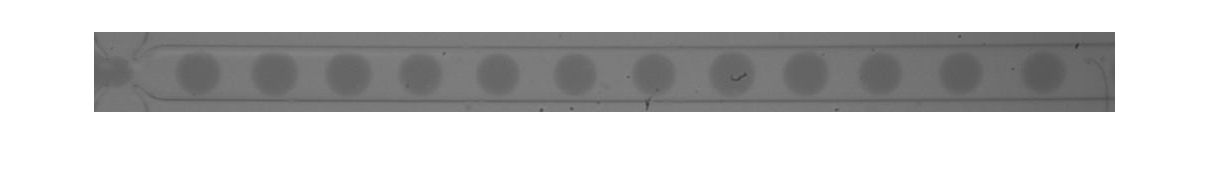

% Load images
I = imread('1014.jpg');   %<-------- user-defined input!!

% check images loaded correctly
figure; imshow(I);  

## 4) Image processing

- Background subtraction

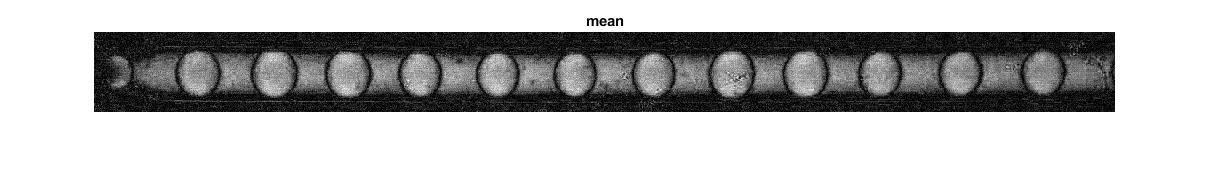

% From Mean background generation
subMean = rescale(abs(double(I) - double(mean_pix))); 
% From Median background generation
subMed = rescale(abs(double(I) - double(med_pix))); %imshow(subMed); 
% From Mode background generation
subMax = rescale(abs(double(I) - double(max_pix))); %imshow(subMax)
% imshowpair(subMed, subMax, 'montage');

% From complex background generation method 
subCom = rescale(abs(double(I) - double(R)));

figure; imshow(subMean); title('mean')

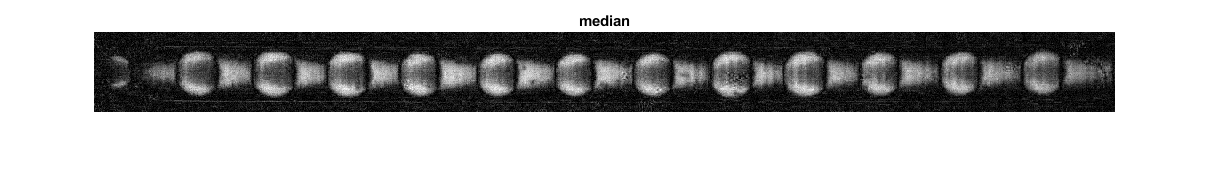

figure; imshow(subMed); title('median')

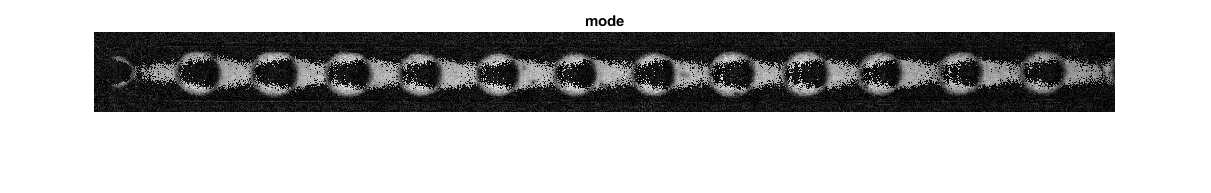


figure; imshow(subMax); title('mode')

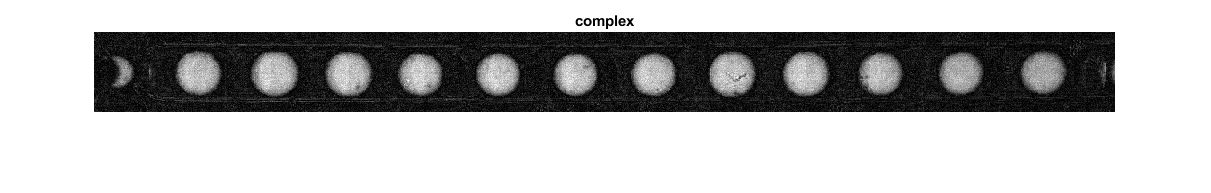

figure; imshow(subCom); title('complex')

- Binarise image

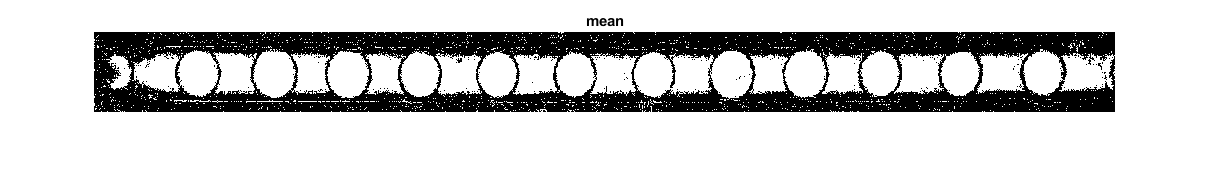

treshold = 0.2; %<-------- user-defined input!!
bin1= imbinarize(subMean, treshold); 
bin2= imbinarize(subMed, treshold);
bin3= imbinarize(subMax, treshold); 
bin4= imbinarize(subCom, treshold); 
% imshowpair(bin1, bin2, 'montage');
figure; imshow(bin1); title('mean')

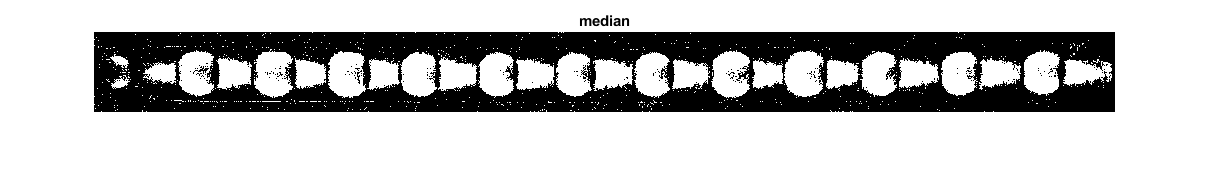

figure; imshow(bin2); title('median')

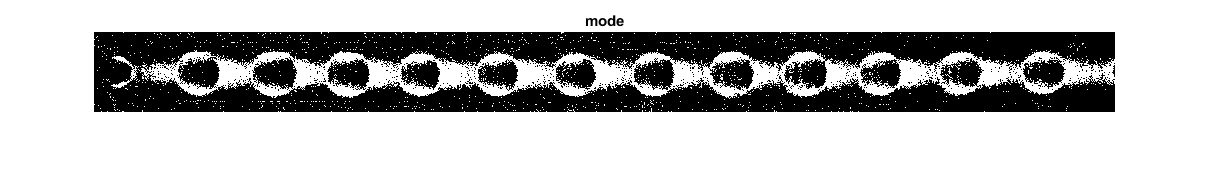


figure; imshow(bin3); title('mode')

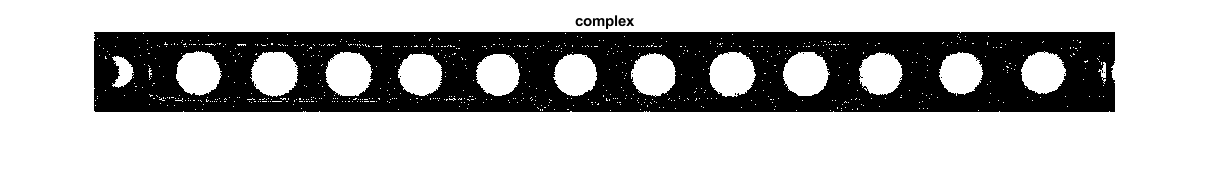

figure; imshow(bin4); title('complex')

- Morphological fill

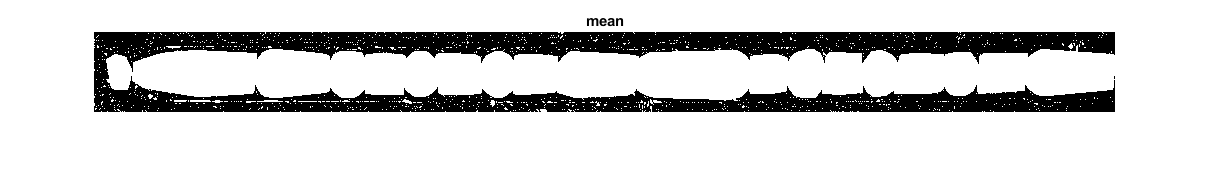

fill1 = bwconvhull(bin1, 'objects'); 
fill2 = bwconvhull(bin2, 'objects'); 
fill3 = bwconvhull(bin3, 'objects'); 
fill4 = bwconvhull(bin4, 'objects'); 
% imshowpair(fill1, fill2, 'montage');
figure; imshow(fill1); title('mean')

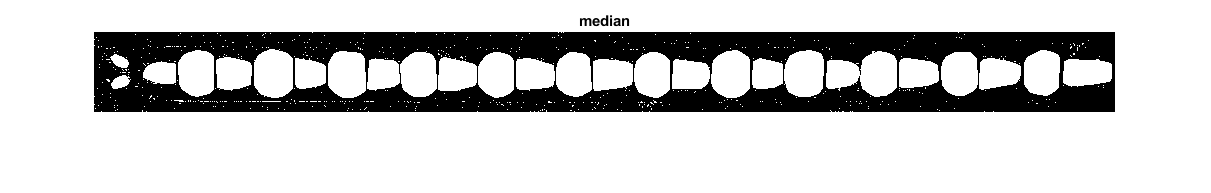

figure; imshow(fill2); title('median')

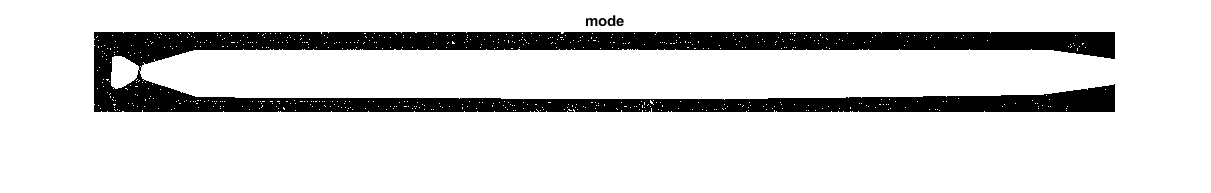

figure; imshow(fill3); title('mode')

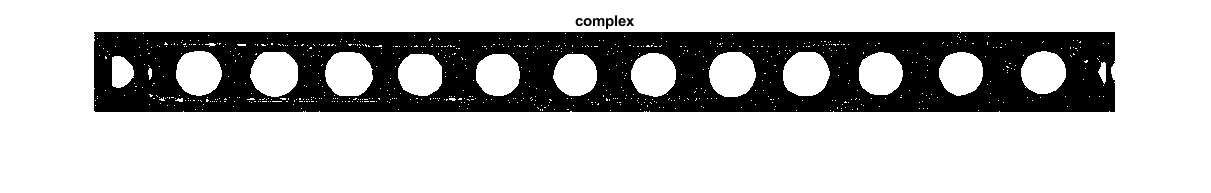

figure; imshow(fill4); title('complex')



%detect ROI
ROI1 = regionprops('table',fill1) 

ROI1 = 1178×3 table
    Area        Centroid                BoundingBox        
    ____    ________________    ___________________________

     2           1       8.5    0.5     7.5       1       2
     1           1        11    0.5    10.5       1       1
     1           1        14    0.5    13.5       1       1
     1           1        16    0.5    15.5       1       1
     1           1        30    0.5    29.5       1       1
     2           1      38.5    0.5    37.5       1       2
     2           1      65.5    0.5    64.5       1       2
     3           1        73    0.5    71.5       1       3
     1           2        63    1.5    62.5       1       1
     3      2.3333    77.333    1.5    76.5       2       2
     3           4         5    2.5     3.5       3       3
     1           3         9    2.5     8.5       1       1
     1           3        48    2.5  

ROI2 = regionprops('table',fill2) 

ROI2 = 599×3 table
    Area    Centroid             BoundingBox        
    ____    _________    ___________________________

     1      1       8    0.5     7.5       1       1
     1      1      14    0.5    13.5       1       1
     1      1      65    0.5    64.5       1       1
     1      1      73    0.5    72.5       1       1
     1      2      77    1.5    76.5       1       1
     1      3       6    2.5     5.5       1       1
     1      4      57    3.5    56.5       1       1
     1      5       9    4.5     8.5       1       1
     2      5    15.5    4.5    14.5       1       2
     1      5      74    4.5    73.5       1       1
     1      6      33    5.5    32.5       1       1
     1      6      36    5.5    35.5       1       1
     1      8      15    7.5    14.5       1       1
     1      8      71    7.5    70.5       1       1
     1      8      80    7.5  

ROI3 = regionprops('table',fill3) 

ROI3 = 676×3 table
    Area     Centroid              BoundingBox        
    ____    ___________    ___________________________

     1        1       8    0.5     7.5       1       1
     1        1      14    0.5    13.5       1       1
     1        1      73    0.5    72.5       1       1
     2      3.5     5.5    2.5     4.5       2       2
     1        4      39    3.5    38.5       1       1
     1        4      57    3.5    56.5       1       1
     1        5       9    4.5     8.5       1       1
     2        5    15.5    4.5    14.5       1       2
     1        5      74    4.5    73.5       1       1
     1        6      36    5.5    35.5       1       1
     1        7      77    6.5    76.5       1       1
     1        8      15    7.5    14.5       1       1
     1        8      80    7.5    79.5       1       1
     1        9      20    8.5    19.5       1       

ROI4 = regionprops('table',fill4) 

ROI4 = 759×3 table
    Area      Centroid              BoundingBox         
    ____    ____________    ____________________________

     1         1       3     0.5     2.5       1       1
     1         1       5     0.5     4.5       1       1
     2         1     8.5     0.5     7.5       1       2
     1         1      57     0.5    56.5       1       1
     1         1      80     0.5    79.5       1       1
     1         2      69     1.5    68.5       1       1
     1         2      74     1.5    73.5       1       1
     1         4       7     3.5     6.5       1       1
     1         4      65     3.5    64.5       1       1
     1         4      67     3.5    66.5       1       1
     1         6      14     5.5    13.5       1       1
     1         6      24     5.5    23.5       1       1
     1        10      17     9.5    16.5       1       1
     5      12.4    26.

- Noise objects removal

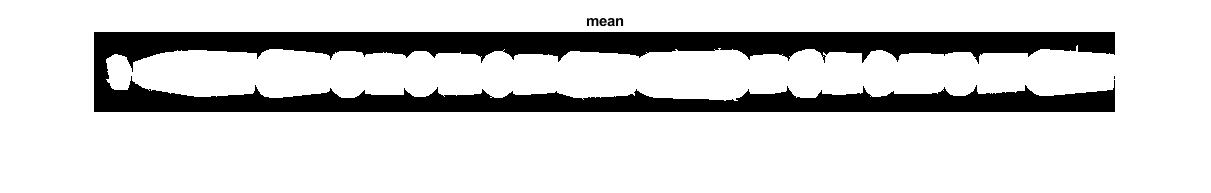

cfill1 = bwareaopen(fill1,1000);
cfill2 = bwareaopen(fill2,1000);
cfill3 = bwareaopen(fill3,1000);
cfill4 = bwareaopen(fill4,1000);

% figure; imshowpair(cfill1, cfill2, 'montage')
figure; imshow(cfill1); title('mean')

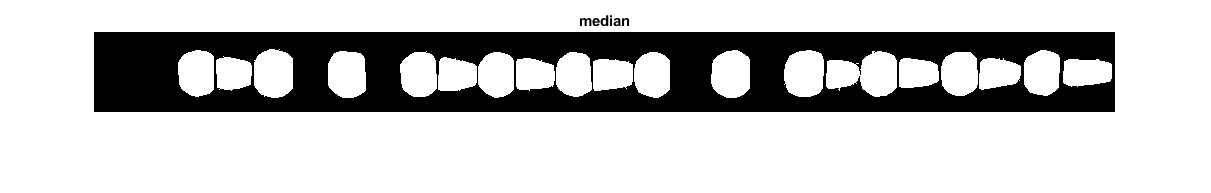

figure; imshow(cfill2); title('median')

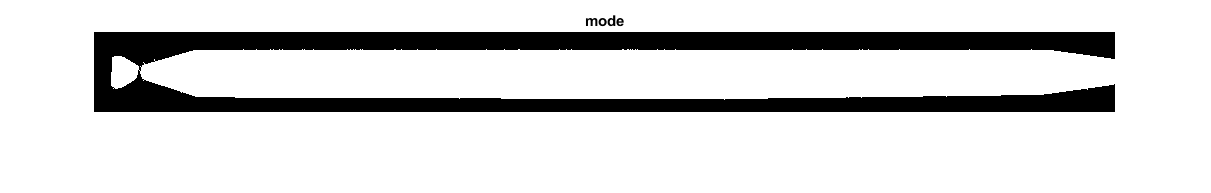

figure; imshow(cfill3); title('mode')

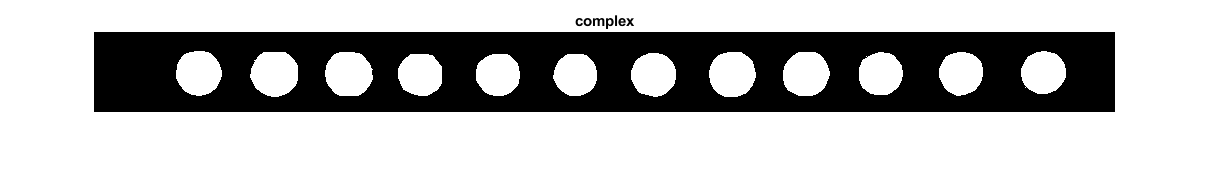

figure; imshow(cfill4); title('complex')


% detect ROI
cROI1 = regionprops('table',cfill1) %ROI1 = struct2table(ROI1)

cROI1 = 1×3 table
    Area        Centroid               BoundingBox         
    _____    ______________    ____________________________

    41803    519.8    42.29    12.5    13.5    1009      56



cROI2 = regionprops('table', cfill2) %ROI2 = struct2table(ROI2)

cROI2 = 19×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    1449    103.36    41.655     84.5     18.5       36       47
    1031    139.68    42.046    122.5     24.5       36       35
    1649    180.27    42.133    160.5     17.5       39       49
    1563    253.78    42.853    234.5     19.5       38       47
    1416    325.62    43.051    306.5     19.5       37       46
    1118    362.78    43.411    344.5     25.5       39       34
    1398    403.26    43.231    384.5     20.5       36       46
    1086    440.62    43.034    422.5     26.5       39       33
    1356    480.71    43.086    462.5     20.5       36       45
    1130    518.38    43.062    499.5     27.5       40       32
    1400    559.22    43.379    540.5     20.5       36       46
    1579    637.75    42.771    6

cROI3 = regionprops('table', cfill3) %ROI3 = struct2table(ROI3)

cROI3 = 1×3 table
    Area         Centroid                BoundingBox         
    _____    ________________    ____________________________

    45504    525.49    42.225    17.5    17.5    1004      51


cROI4 = regionprops('table',cfill4) %ROI4 = struct2table(ROI4)

cROI4 = 12×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    1629    105.22    41.596     82.5     19.5       46       45
    1736    181.19    42.255    156.5     20.5       48       45
    1720    255.23    42.553    231.5     20.5       48       44
    1525    326.94    43.115    304.5     22.5       44       42
    1502    404.59    43.216    382.5     22.5       44       42
    1477    482.09    43.276    459.5     22.5       44       42
    1564    560.17    43.235    537.5     21.5       45       44
    1702    638.79    42.862    615.5     20.5       47       45
    1667    712.57     42.53    689.5     20.5       47       44
    1519    787.14    42.335    765.5     20.5       44       43
    1516    867.63    41.888    845.5     20.5       44       44
    1521    950.01    41.081    9

- Remove drops outside of main flow channel

delCriteria = 100; % remove drop if centroid position < delCritera  <-------- user-defined input!!

cROI1(cROI1.Centroid(:,1) < delCriteria, :) = []

cROI1 = 1×3 table
    Area        Centroid               BoundingBox         
    _____    ______________    ____________________________

    41803    519.8    42.29    12.5    13.5    1009      56


cROI2(cROI2.Centroid(:,1) < delCriteria, :) = []

cROI2 = 19×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    1449    103.36    41.655     84.5     18.5       36       47
    1031    139.68    42.046    122.5     24.5       36       35
    1649    180.27    42.133    160.5     17.5       39       49
    1563    253.78    42.853    234.5     19.5       38       47
    1416    325.62    43.051    306.5     19.5       37       46
    1118    362.78    43.411    344.5     25.5       39       34
    1398    403.26    43.231    384.5     20.5       36       46
    1086    440.62    43.034    422.5     26.5       39       33
    1356    480.71    43.086    462.5     20.5       36       45
    1130    518.38    43.062    499.5     27.5       40       32
    1400    559.22    43.379    540.5     20.5       36       46
    1579    637.75    42.771    6

cROI3(cROI3.Centroid(:,1) < delCriteria, :) = []

cROI3 = 1×3 table
    Area         Centroid                BoundingBox         
    _____    ________________    ____________________________

    45504    525.49    42.225    17.5    17.5    1004      51



cROI4(cROI4.Centroid(:,1) < delCriteria, :) = []

cROI4 = 12×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    1629    105.22    41.596     82.5     19.5       46       45
    1736    181.19    42.255    156.5     20.5       48       45
    1720    255.23    42.553    231.5     20.5       48       44
    1525    326.94    43.115    304.5     22.5       44       42
    1502    404.59    43.216    382.5     22.5       44       42
    1477    482.09    43.276    459.5     22.5       44       42
    1564    560.17    43.235    537.5     21.5       45       44
    1702    638.79    42.862    615.5     20.5       47       45
    1667    712.57     42.53    689.5     20.5       47       44
    1519    787.14    42.335    765.5     20.5       44       43
    1516    867.63    41.888    845.5     20.5       44       44
    1521    950.01    41.081    9

## 5) Plot results

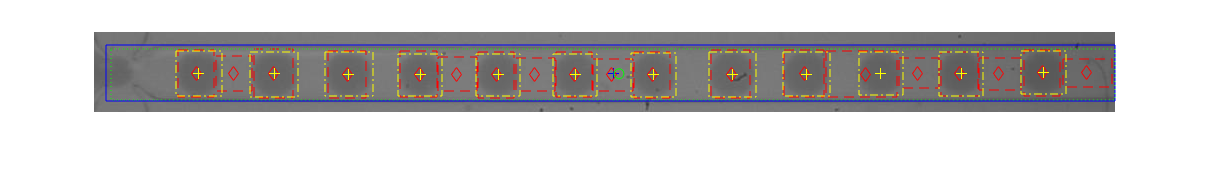

figure; imshow(I);
hold on

% from ROI1 data
plot(cROI1.Centroid(:,1), cROI1.Centroid(:,2), 'b+')

for i=1:height(cROI1)
    rectangle('Position',cROI1.BoundingBox(i,:),'EdgeColor','b')
end

% from ROI2 data
plot(cROI2.Centroid(:,1), cROI2.Centroid(:,2), 'rd')

for i=1:height(cROI2)
    rectangle('Position',cROI2.BoundingBox(i,:),'EdgeColor','r','LineStyle', '--')
end

% from ROI3 data
plot(cROI3.Centroid(:,1), cROI3.Centroid(:,2), 'go')

for i=1:height(cROI3)
    rectangle('Position',cROI3.BoundingBox(i,:),'EdgeColor','g','LineStyle', ':')
end

% from ROI4 data
plot(cROI4.Centroid(:,1), cROI4.Centroid(:,2), "y+")

for i=1:height(cROI4)
    rectangle('Position',cROI4.BoundingBox(i,:),'EdgeColor','y','LineStyle', '-.')
end

## 6) Crop and show individual drops 

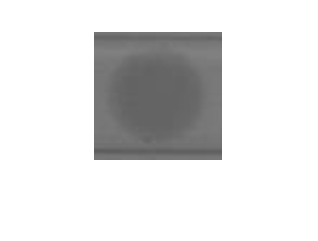

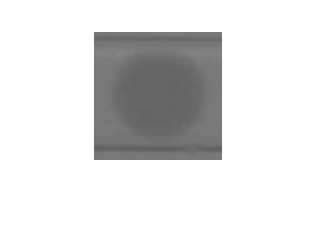

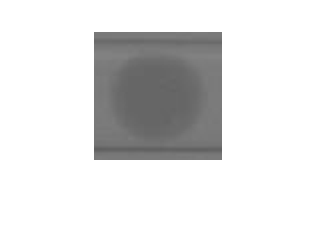

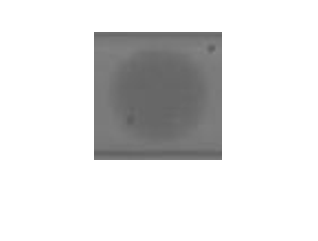

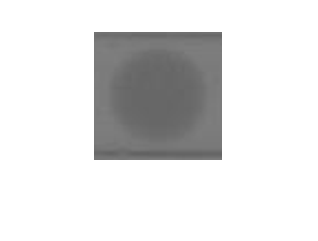

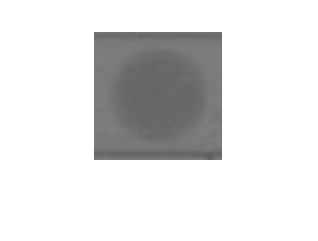

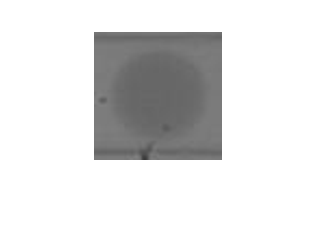

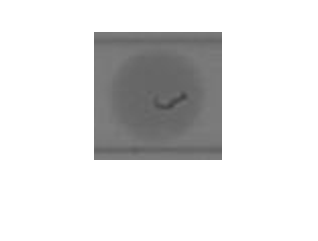

 
roiTable = cROI4.BoundingBox; 
cropSize = [128 128];

for i = 1: height(roiTable)
    dim = max([roiTable(i,3:4)]); % this will be the width/ height of square cropped area
    % x-coord of centroid of cropping region
    cx = roiTable(i,1) + roiTable(i,3)/2; 
    % y-coord of centroid of cropping region
    cy = roiTable(i,2) + roiTable(i,4)/2; 
    
    % coordinates of bottom-left vertex of intended crop region 
    xmin = cx - dim/2 - 0.15*dim;
    ymin = cy - dim/2 - 0.15*dim; 
    
    % crop region defined as [x-coord of bottom left point, y-coord of
    % bottom left point, width, height]
    Img = imcrop(I, [xmin, ymin, 1.3*dim, 1.3*dim]);
    
    % resize cropped image
    Img = imresize(Img, cropSize);
    
    %show image
    figure; imshow(Img)
end 

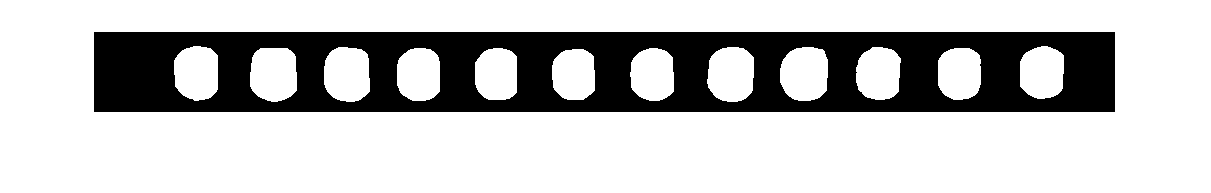

% % test= bwmorph(fill1,'remove');
% se = strel('disk', round(0.15*min(cROI1.BoundingBox(:,3))));
% test = imdilate(cfill1,se);
% figure; imshow(test)

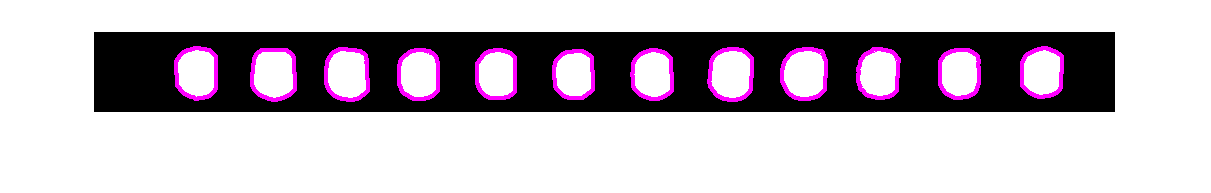

% figure; imshowpair(cfill1,test)